## Section A: Data Preparation

#### Part 1: Use the plot command to view the time series sensor data for the variables Pressure, Vibration and Temperature (PVT) and the Electrodes. Do this for several objects and trials and then choose a single time step that looks like it will allow differentiation between the data for different objects. Explain why you chose that value. Include an example of your data visualisation for one or two object trials in your report.

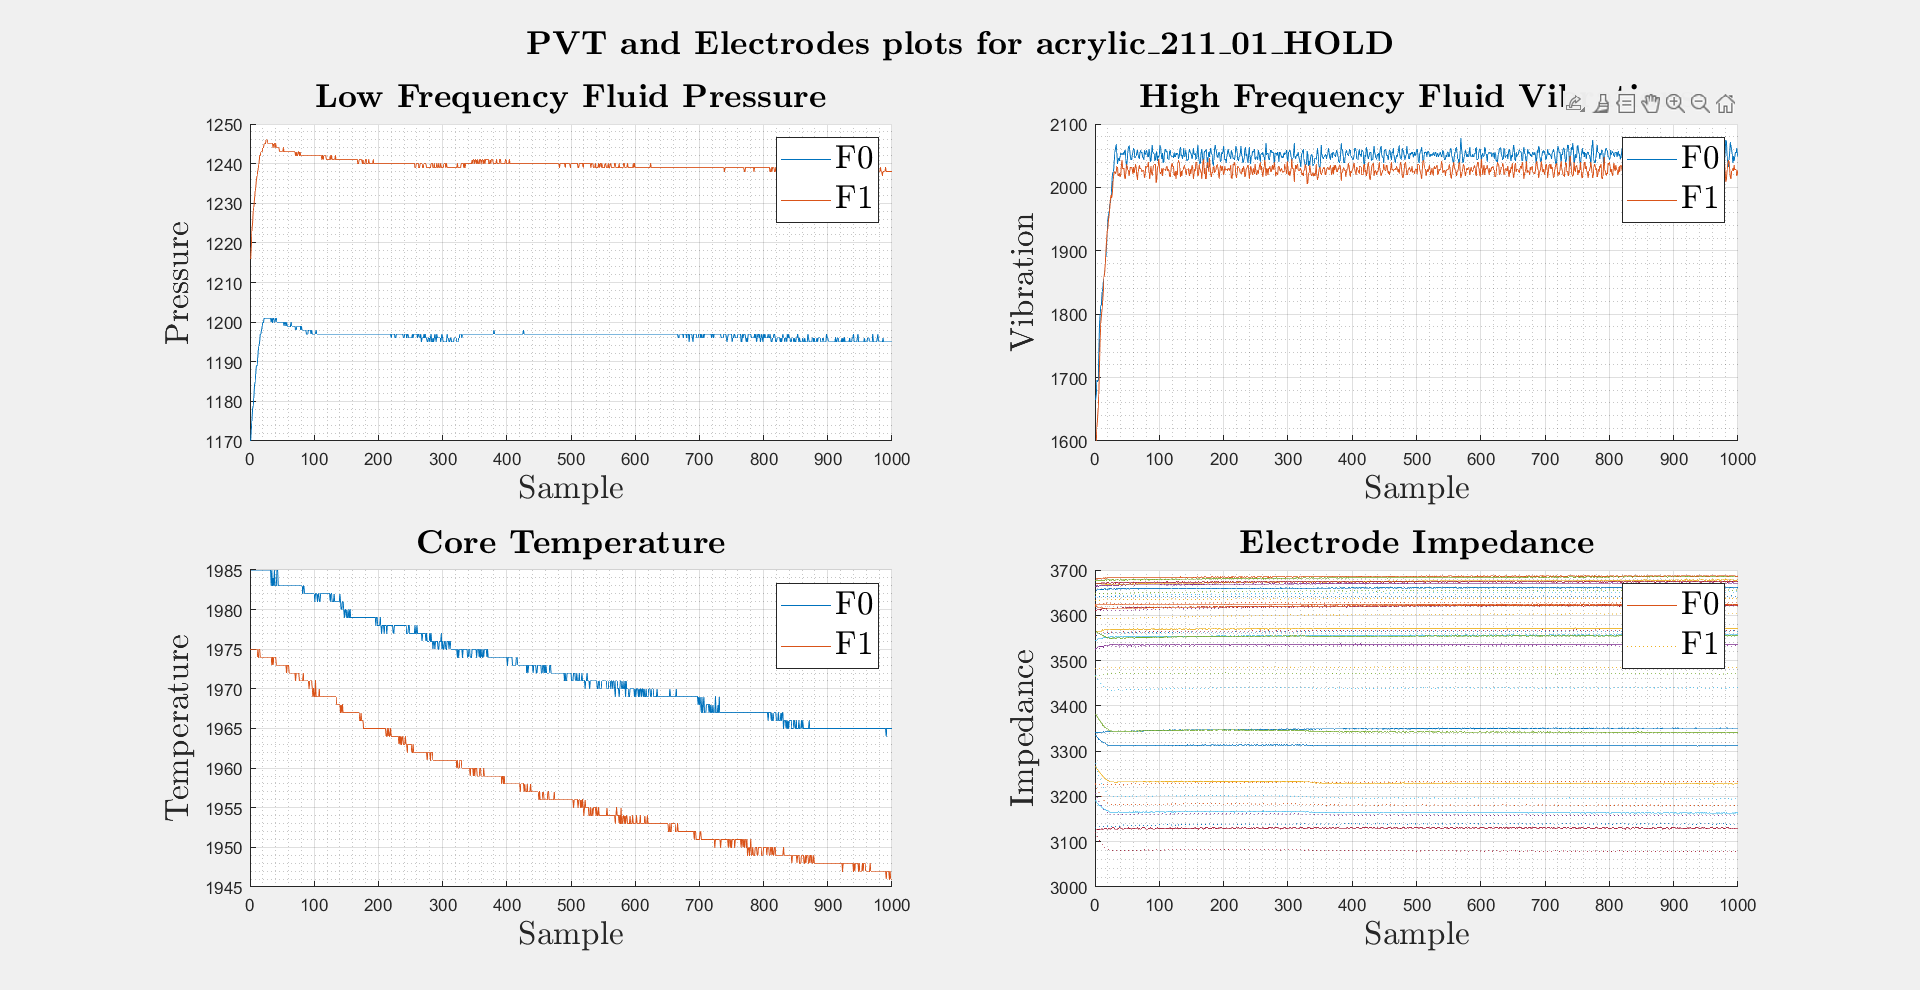

clc, clear, close all

% load data
fileName = 'kitchen_sponge_114_02_HOLD';

% kitchen_sponge_114_02_HOLD
% acrylic_211_01_HOLD
% black_foam_110_03_HOLD
% flour_sack_410_02_HOLD

load(strcat('PR_CW_DATA_2022','/',fileName,'.mat')) 

% plot pressure
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
subplot(2,2,1)
hold on
plot(F0pdc)
plot(F1pdc)
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Low Frequency Fluid Pressure}','Interpreter', 'Latex', 'Fontsize', 20)

% plot vibration
subplot(2,2,2)
hold on
plot(F0pac(2,:))
plot(F1pac(2,:))
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{High Frequency Fluid Vibrations}','Interpreter', 'Latex', 'Fontsize', 20)

% plot temperature 
subplot(2,2,3)
hold on
plot(F0tdc)
plot(F1tdc)
legend(['F0';'F1'],'Interpreter', 'Latex', 'Fontsize', 20)
grid on
grid minor
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Temperature', 'Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Core Temperature}','Interpreter', 'Latex', 'Fontsize', 20)

% plot impedance 
subplot(2,2,4)
hold on
for row= 1:19
    h1 = plot(F0Electrodes(row,:), 'LineStyle','-');
    h2 = plot(F1Electrodes(row,:), 'LineStyle',':');
end
grid on
grid minor
legend([h1 h2],'F0','F1','Interpreter', 'Latex', 'Fontsize', 20)
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Impedance', 'Interpreter', 'Latex', 'Fontsize', 20)
title('\textbf{Electrode Impedance}','Interpreter', 'Latex', 'Fontsize', 20)

% saveas(gca, fullfile('figures', 'pr_a_1'), 'epsc2');

fileNameTitle = strrep(fileName, '_', '\_');
sgtitle(['\textbf{PVT and Electrodes plots for ',fileNameTitle, '}'], 'Fontsize', 20, 'Interpreter', 'Latex')

hold off;

#### Part 2: For one finger (F0 or F1), sample the Pressure, Vibration, Temperature time series data into scaler values measured at the time instance (of your selected time step) for each object / trial. Save the data structures together as a .mat file called F0_PVT.mat or F1_PVT.mat. Repeat for the Electrodes data, saving that as another .mat file. Note that all subsequent actions in this coursework will be on the data sets you just created (and therefore only on one of the robot’s fingers).

dirName = 'PR_CW_DATA_2022';
timestep = 750;                                 % sample to use for comparison
PVT = struct;                                   %  struct for data for all materials at chosen timestep
Electrodes = struct;
myDir = dirName;
myFiles = dir(fullfile(dirName,'*.mat'));       % get all mat files in directory
for k = 1:length(myFiles)
  baseFileName = myFiles(k).name;
  fullFileName = fullfile(myDir, baseFileName);
  load(fullFileName);
  % read data from each file into structs - change 'F0' to 'F1' to get data for different finger
  PVT(k).name = baseFileName;
  PVT(k).pressure = F0pdc(timestep);
  PVT(k).vibration = F0pac(2,timestep);
  PVT(k).temperature = F0tdc(timestep);
  Electrodes(k).name = baseFileName;
  Electrodes(k).impedance = F0Electrodes(:,timestep);
  save('F0_PVT.mat', 'PVT')
  save('F0_Electrodes.mat', 'Electrodes')
end

#### Part 3: Create a 3D scatter plot of the complete contents of the PVT .mat file, with the axis as Pressure, Vibration and Temperature, with different colours used for different objects. Use the same colours for the objects throughout this work.

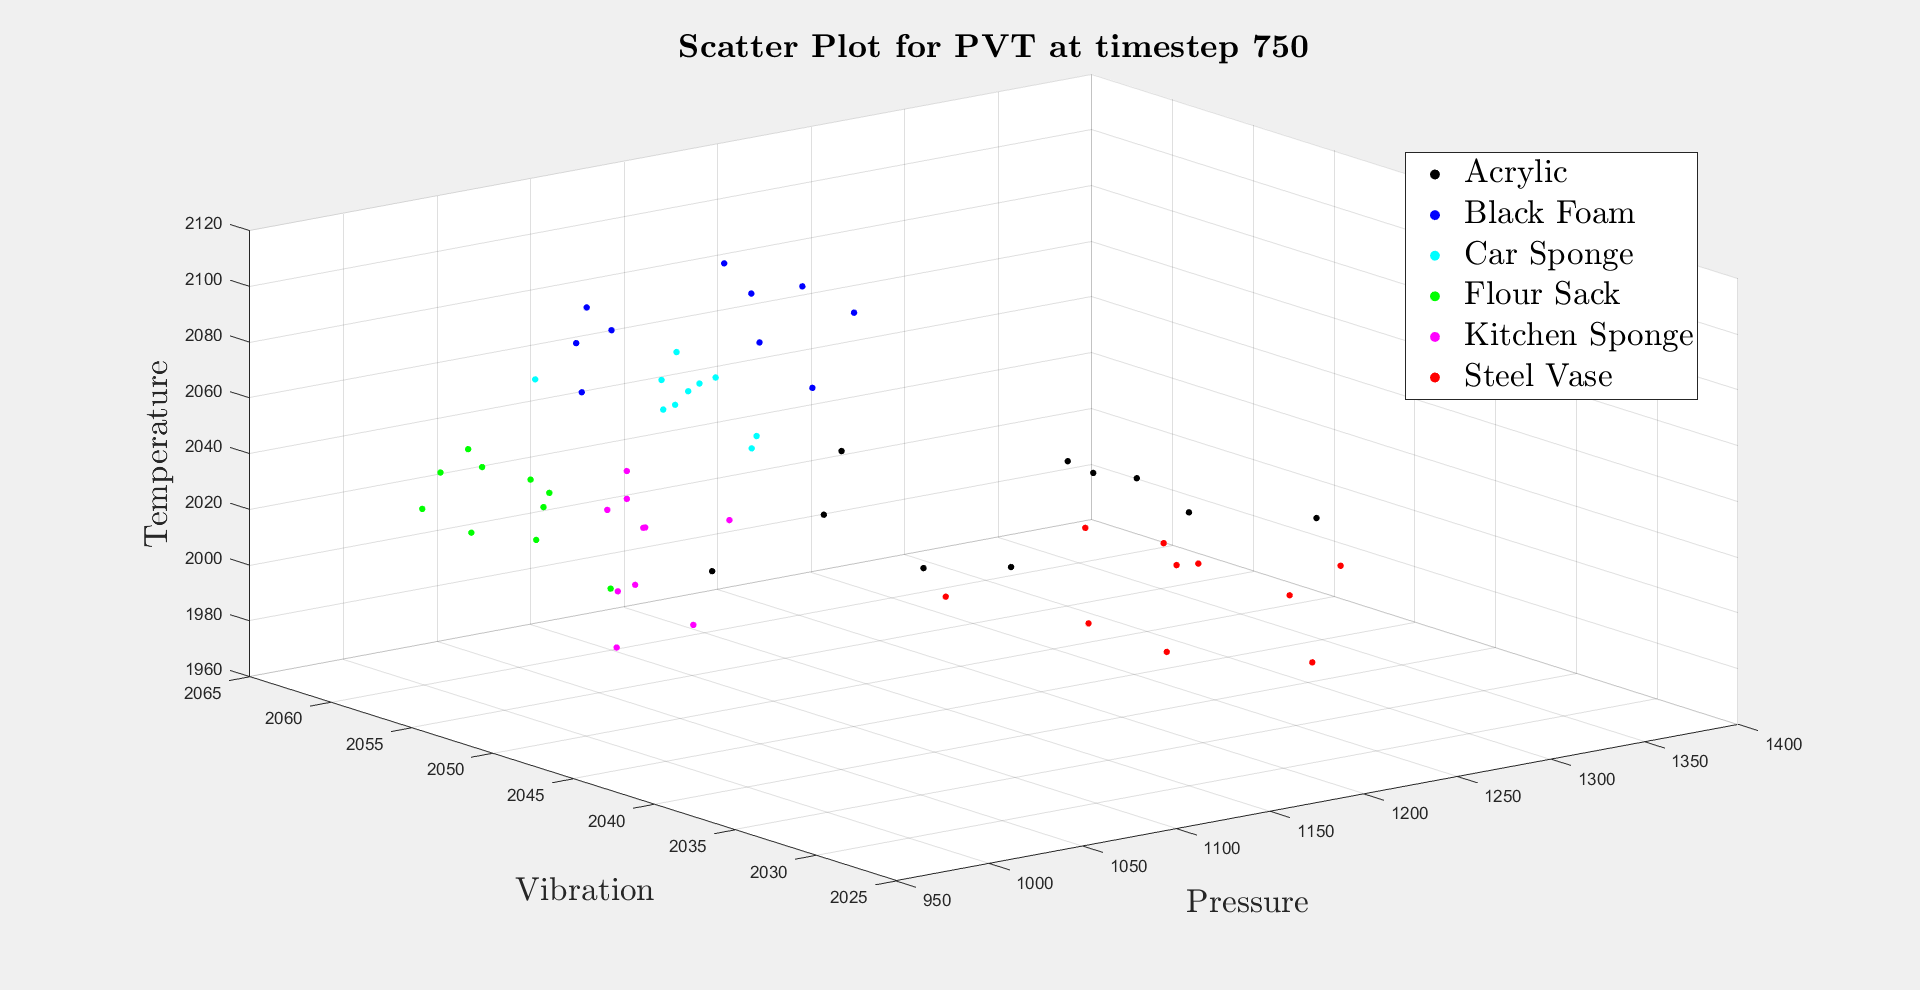

% load data
F0_PVT = load('F0_PVT.mat').PVT;
F0_Electrodes = load('F0_Electrodes.mat').Electrodes;

pressure = zeros(1,60);
vibration = zeros(1,60);
temperature = zeros(1,60);

% get data into individual variables
for i = 1:60
    pressure(i) = F0_PVT(i).pressure;
    vibration(i) = F0_PVT(i).vibration;
    temperature(i) = F0_PVT(i).temperature;
end

colourNames = {'black', 'blue', 'cyan', 'green', 'magenta', 'red'};

% scatter plot
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter3(pressure(1:10),vibration(1:10),temperature(1:10),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(pressure((i*10)+1:(i+1)*10),vibration((i*10)+1:(i+1)*10),temperature((i*10)+1:(i+1)*10),15,colourNames{i+1},'filled')
end

xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title(['\textbf{Scatter Plot for PVT at timestep ', num2str(timestep), '}'],'Interpreter', 'Latex', 'Fontsize', 20)
hold off;

% saveas(gca, fullfile('figures', 'pr_a_2'), 'epsc2');


## Section B: Principal Component Analysis

#### Part 1: Using PCA (Principal Component Analysis) determine the principal components of the PVT data.

**a) Report covariance matrix, eigenvalues, and eigenvectors for the data.**

% get the covariance matrix
Q = [pressure;vibration;temperature];
Q = Q';

A = [pressure;vibration;temperature];
C = cov(A);                 % C = covariance matrix

% finding Eigenvectors
[V,D] = eig(C);         % V = the corresponding eigenvectors 
D=diag(D);              % these are the corresponding eigenvalues

% returns the eigenvector for the maximum eigenvalue
maxeigval= V(:,find(D==max(D))); 

% standardize the data
A = bsxfun(@minus,A',mean(A'))./ std(A');

% Do the PCA
[coeff,score,latent] = pca(A); % coeff = feature vector for eigenvectors

% Calculate eigenvalues and eigenvectors of the covariance matrix
SC = cov(A);

[SV,SD] = eig(SC);
SD=diag(SD);

coeff = coeff*-1;   % compared to SV and SD the eigenvector were multiplied by -1 except the last column (unknown why)
coeff(:,end) = coeff(:,end)*-1; % the last eigenvector was as supposed to be so returning it to original

**b) Replot the Standardised data with the Principal components displayed.**

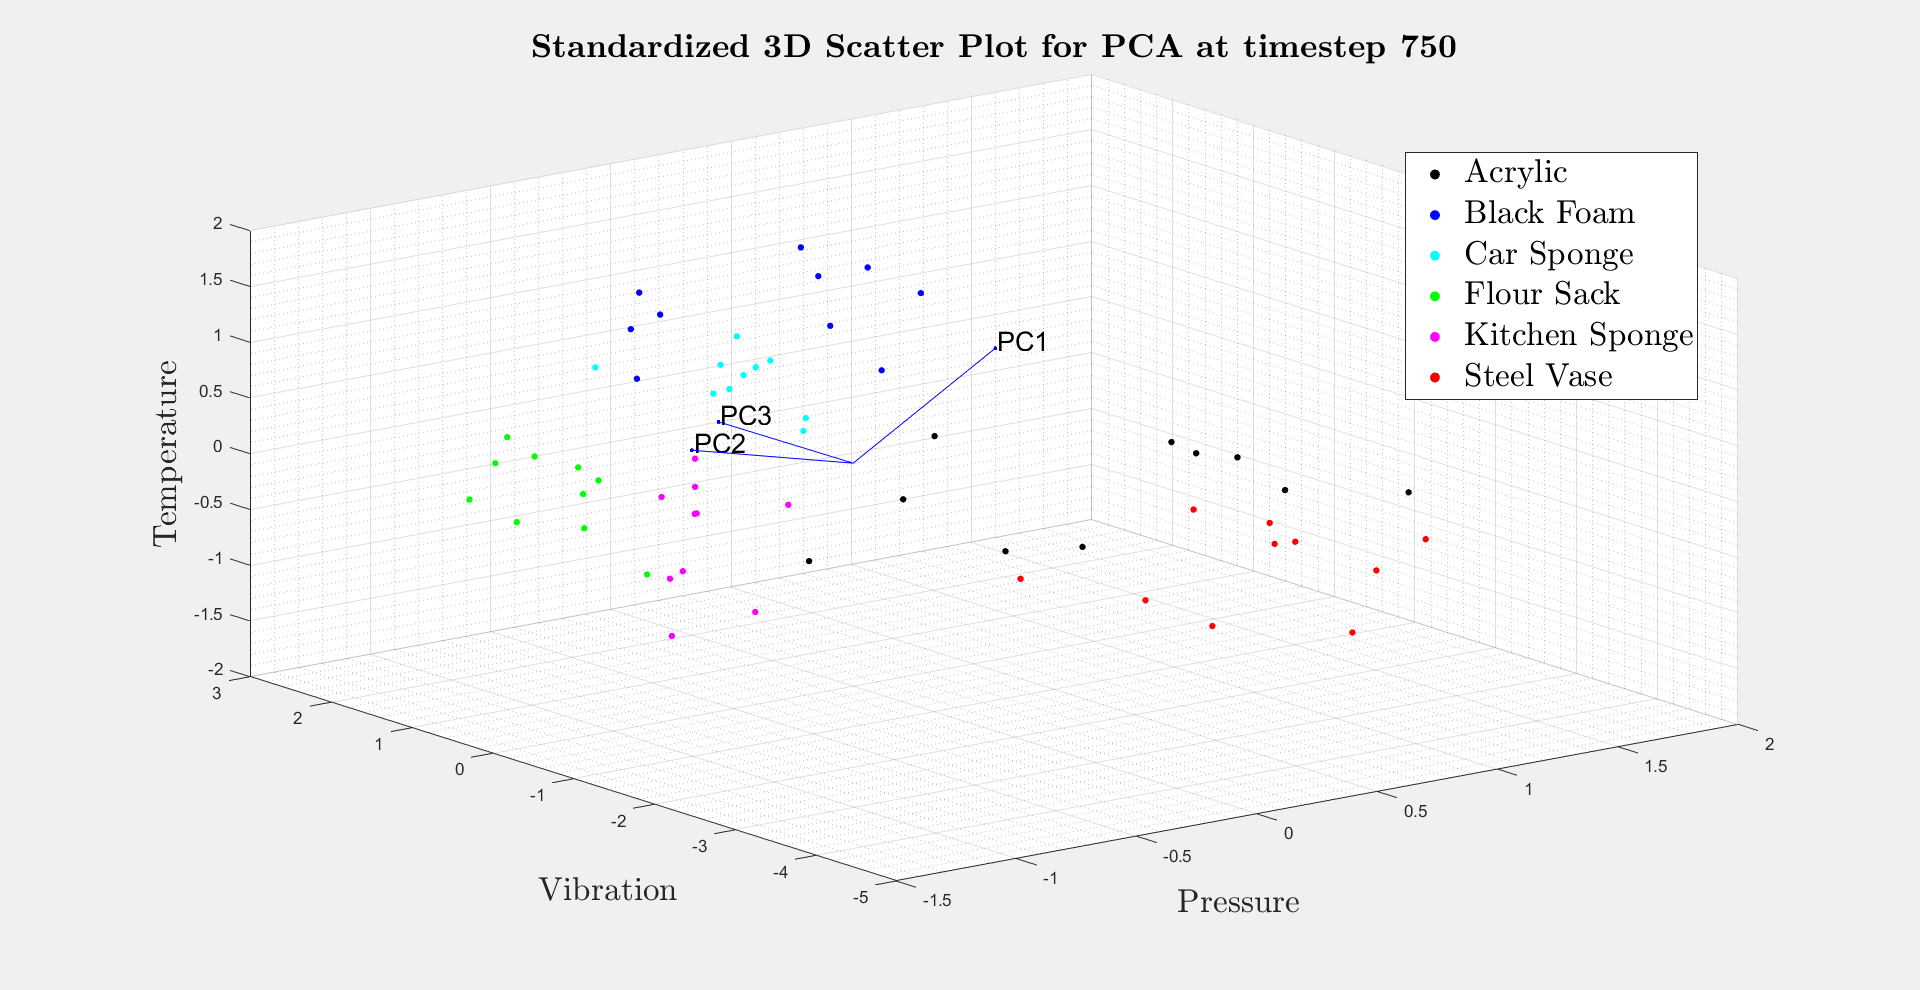

% Re-plot scatter plot for standardized data
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter3(A((1:10),1),A((1:10),2),A((1:10),3),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(A(((i*10)+1:(i+1)*10),1),A(((i*10)+1:(i+1)*10),2),A(((i*10)+1:(i+1)*10),3),15,colourNames{i+1},'filled')
end
vbls = {'PC1','PC2','PC3'}; % Labels for the variables
bip = biplot(coeff(:,1:3),'VarLabels',vbls); % plot the PC in the scatter plot
for k = 7:9
    bip(k).FontSize = 16;
end
grid on
grid minor
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title(['\textbf{Standardized 3D Scatter Plot for PCA at timestep ', num2str(timestep), '}'], 'Interpreter', 'Latex', 'Fontsize', 20)
hold off

% saveas(gca, fullfile('figures', 'pr_b_1'), 'epsc2');

#### c) Reduce the data to 2-dimensions and replot.

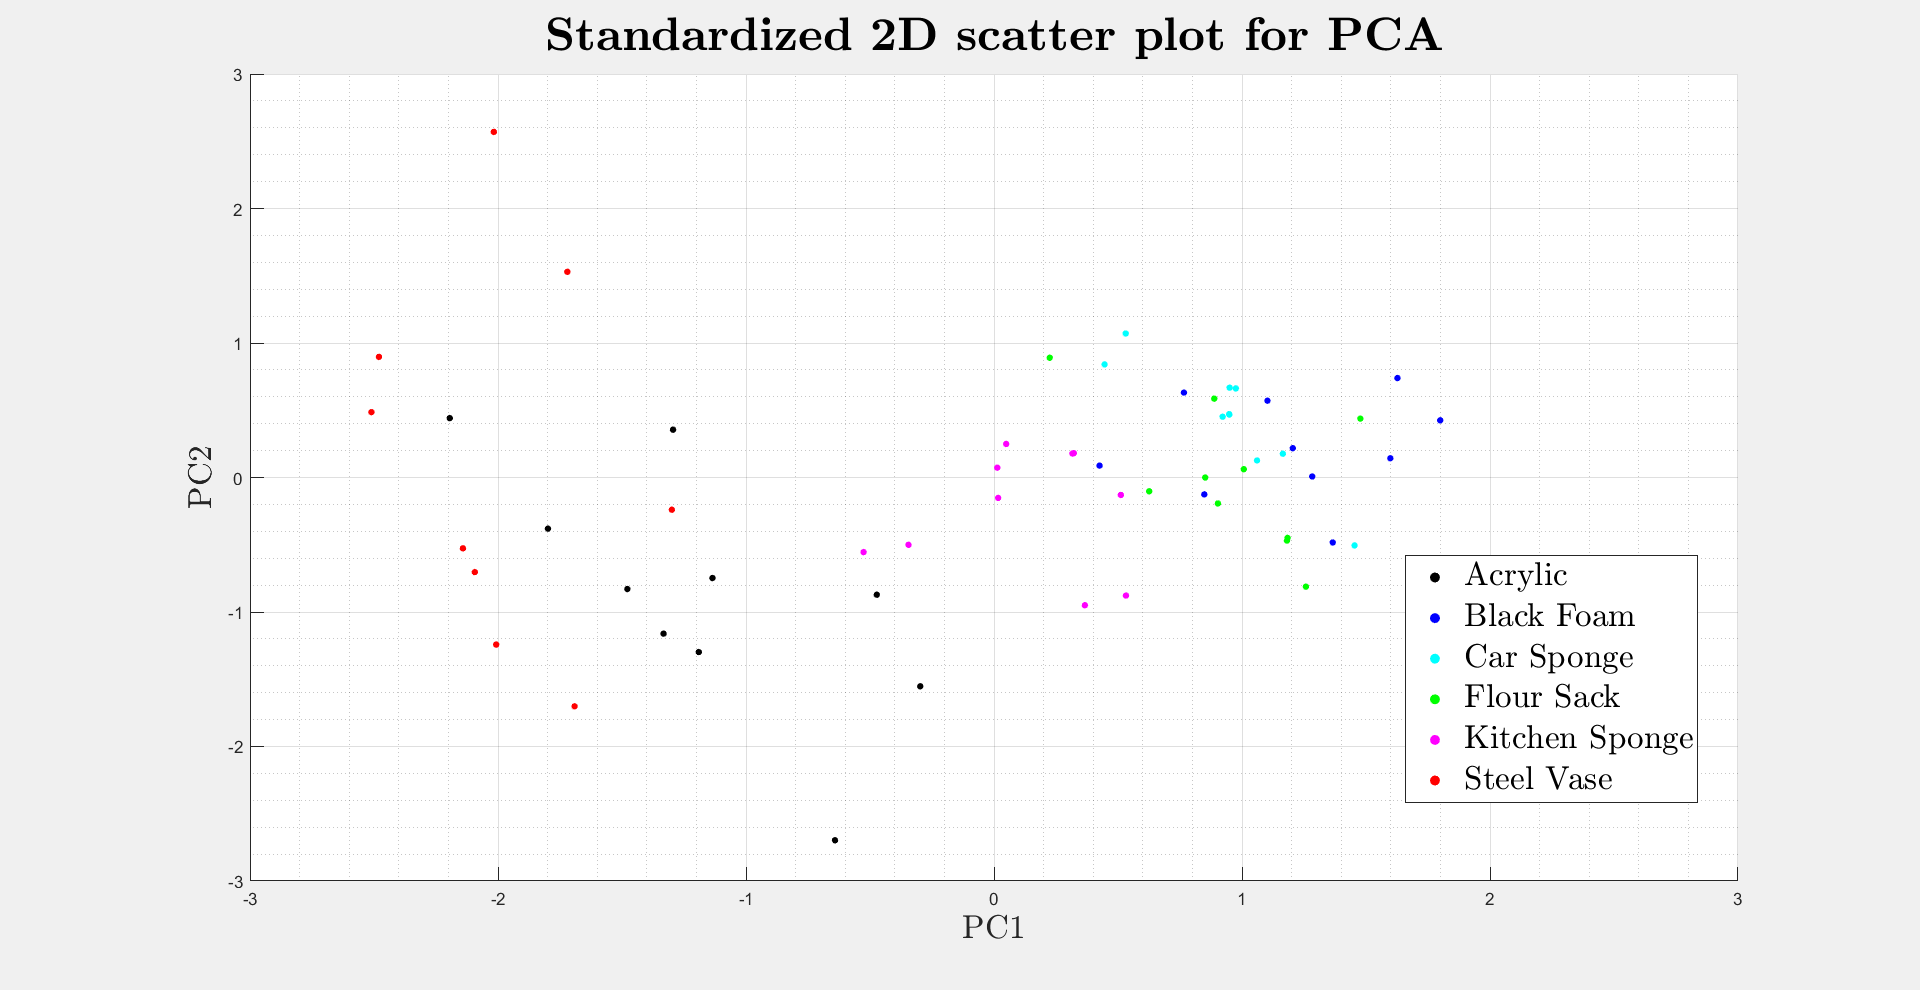

PC3_coeff = coeff(:,end); %Get last column as PC3
PC2_coeff = coeff(:,2);   %Get SECOND column as PC2
PC1_coeff = coeff(:,1);   %Get FIRST column as PC1

% Create projected matrix onto the Principle Components
coeff(:,end) = []; % Delete last column to get feature vector for 2D data
P = A*coeff;    % Get 2D projected data

% Re-plot scatter plot for standardized data
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
scatter(P((1:10),1),P((1:10),2),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter(P(((i*10)+1:(i+1)*10),1),P(((i*10)+1:(i+1)*10),2),15,colourNames{i+1},'filled')
end

axis([-3 3 -3 3])
grid on
grid minor
xlabel('PC1','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('PC2','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
title('\textbf{Standardized 2D scatter plot for PCA}', 'Interpreter', 'Latex', 'Fontsize', 28)

% saveas(gca, fullfile('figures', 'pr_b_2'), 'epsc2');

#### d) Show how the data is distributed across all principal components by plotting as separate 1D number lines.

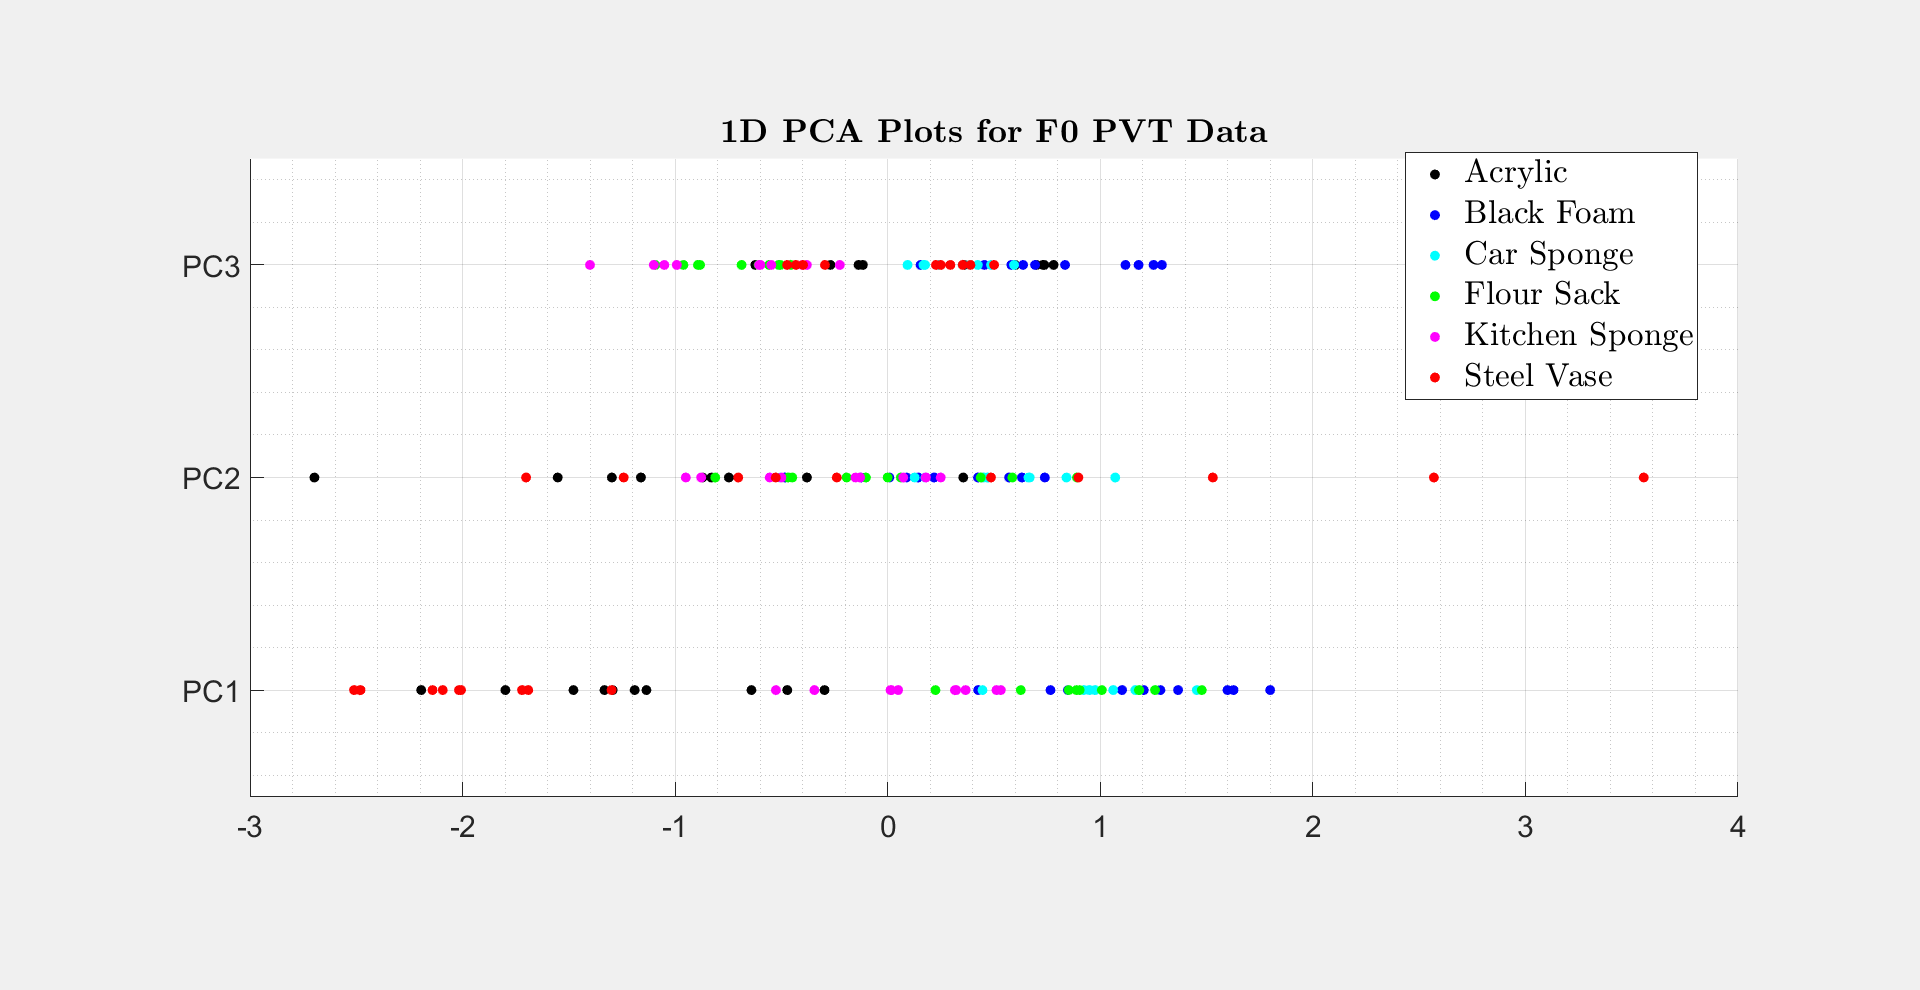

PC1 = A*PC1_coeff;  % Project onto PC1 to get 1D Data
PC2 = A*PC2_coeff;  % Project onto PC2 to get 1D Data
PC3 = A*PC3_coeff;  % Project onto PC3 to get 1D Data

% Create projected matrix onto the Principle Components
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
hAxes = axes('NextPlot','add', 'DataAspectRatio',[1 1 1], 'YLim',[0.5 3.5], 'Color','white');

legNames = {'Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase'};

plotHandles = zeros(6,10);

hold on
    for i = 1:6
        plotHandles(i,:) = scatter(hAxes, PC1(((i-1)*10)+1:i*10),1,colourNames{i}, 'filled');
        scatter(hAxes, PC2(((i-1)*10)+1:i*10),2,colourNames{i}, 'filled');  %# Plot data set 2 (show at y = 2)
        scatter(hAxes, PC3(((i-1)*10)+1:i*10),3,colourNames{i}, 'filled');  %# Plot data set 3 (show at y = 3) 
    end
hold off

legend(plotHandles(:,1), legNames,'Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')

grid on
grid minor
yticks([1, 2, 3]) % Show only ticks for the 3 PC
yticklabels({'PC1', 'PC2', 'PC3'}) % Replace tick values with PC names
a = get(gca,'YTickLabel');
set(gca,'YTickLabel',a, 'fontsize',18)
title('\textbf{1D PCA Plots for F0 PVT Data}', 'Interpreter', 'Latex', 'Fontsize', 20)

% saveas(gca, fullfile('figures', 'pr_b_3'), 'epsc2');

#### Part 2: There are 19 electrodes per sensor, so relationship between the electrodes for different objects cannot be easily visualised as in the last questions.

#### a) Use PCA to determine the principal components of the electrode data. Report on the variances of each principal components using a Scree plot.

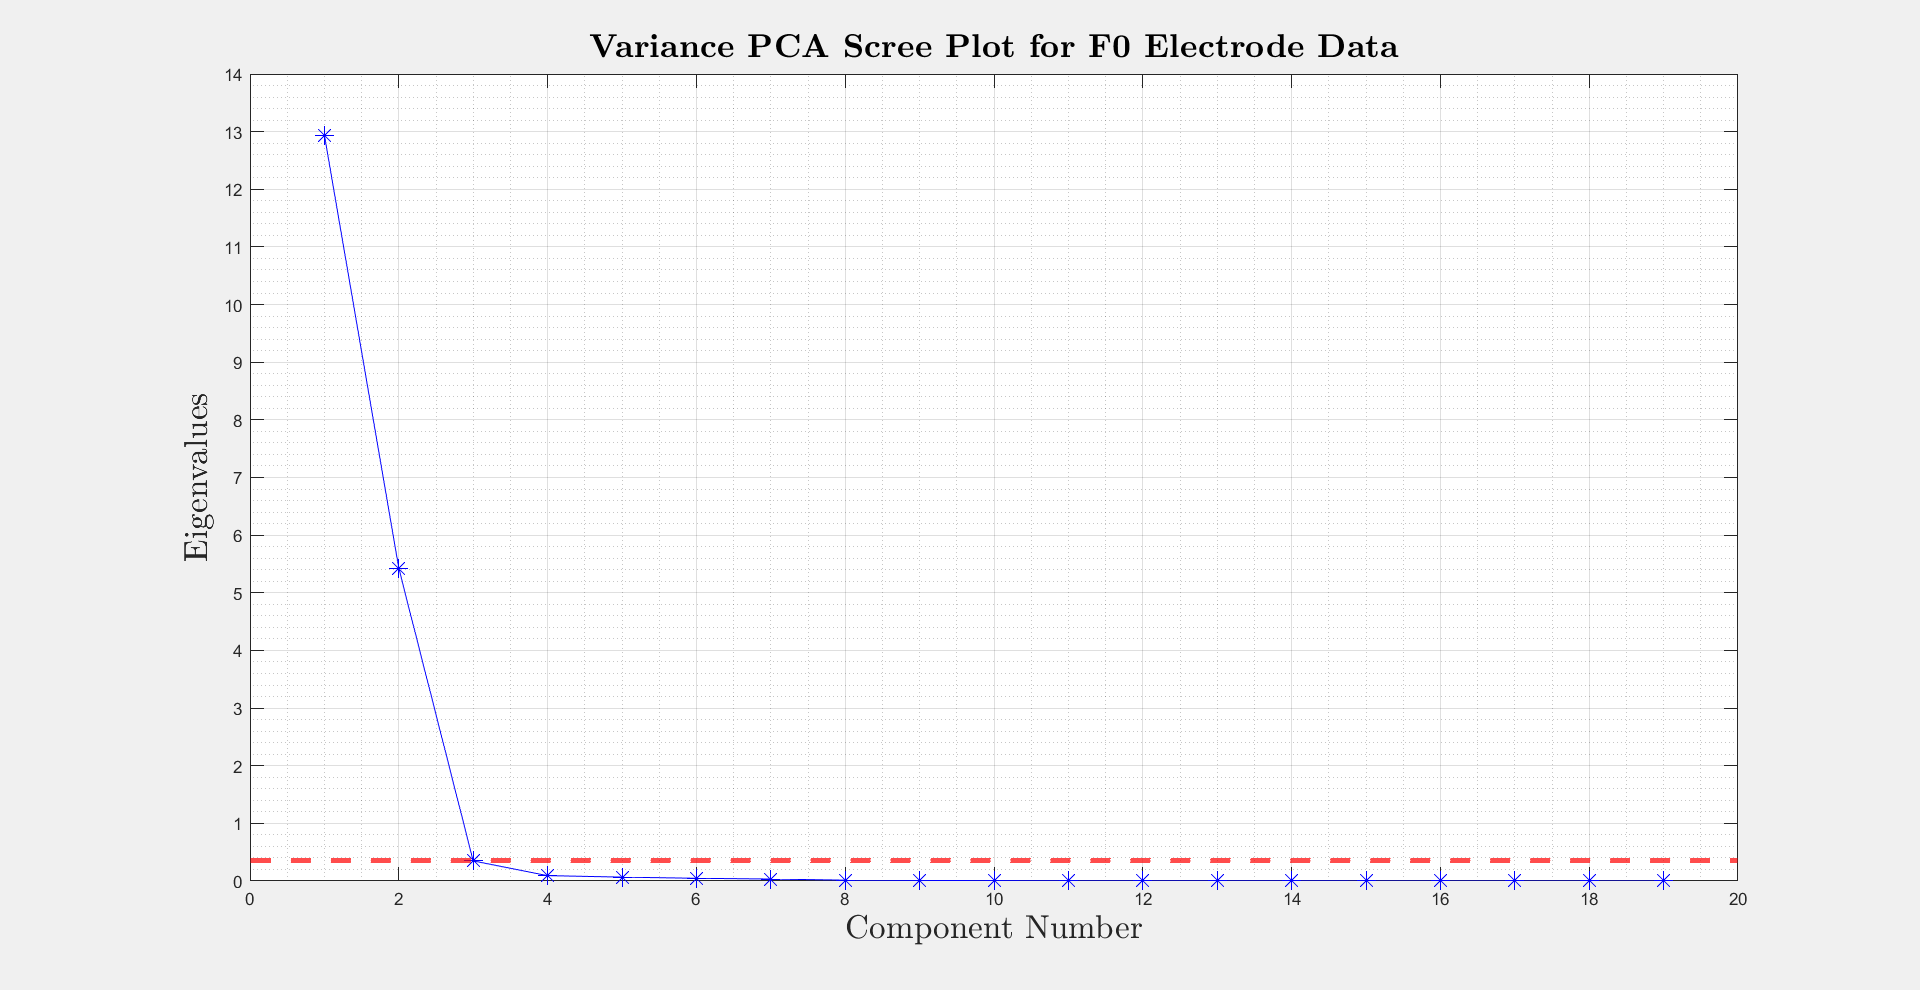

% Get electrodes data for one finger (F0) - same as for PVT
labels = zeros(1,60);
features = zeros(19,60);
for i = 1:60
    features(:,i) = F0_Electrodes(i).impedance;
    labels(i) = floor((i-1)/10);
    %E = [E; {F0_Electrodes_500(v).impedance}];
end

E = features;

% standardize the data
E = bsxfun(@minus,E',mean(E'))./ std(E');

% Calculate eigenvalues and eigenvectors of the covariance matrix
SCE = cov(E);
[SVE,SDE] = eig(SCE);
SDE=diag(SDE);
maxeigvalE= SVE(:,find(SDE==max(SDE))); % Get first PC eigenvector

% Get variance of each component by finding corresponding eigenvalues
[Ecoeff, Escore, eigenvalues] = pca(E); % Check that variables match with eigenvectors and eigenvalues found

% Make scree plot of PC 
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
plot(eigenvalues, 'b*-', 'MarkerSize',10); % Plot Eigenvalues per Component Number
hold on
yline(eigenvalues(3), 'LineStyle', '--', 'Color', 'r', 'LineWidth', 3)
grid on
grid minor
xlabel('Component Number','Interpreter', 'Latex', 'Fontsize', 20) 
ylabel('Eigenvalues','Interpreter', 'Latex', 'Fontsize', 20)
set(gca,'YTick',0:1:15) % Set more ticks in y-axis
title('\textbf{Variance PCA Scree Plot for F0 Electrode Data}','Interpreter', 'Latex', 'Fontsize', 20)

% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');

#### b) Visualize the electrode data using the three principal components with largest variance.

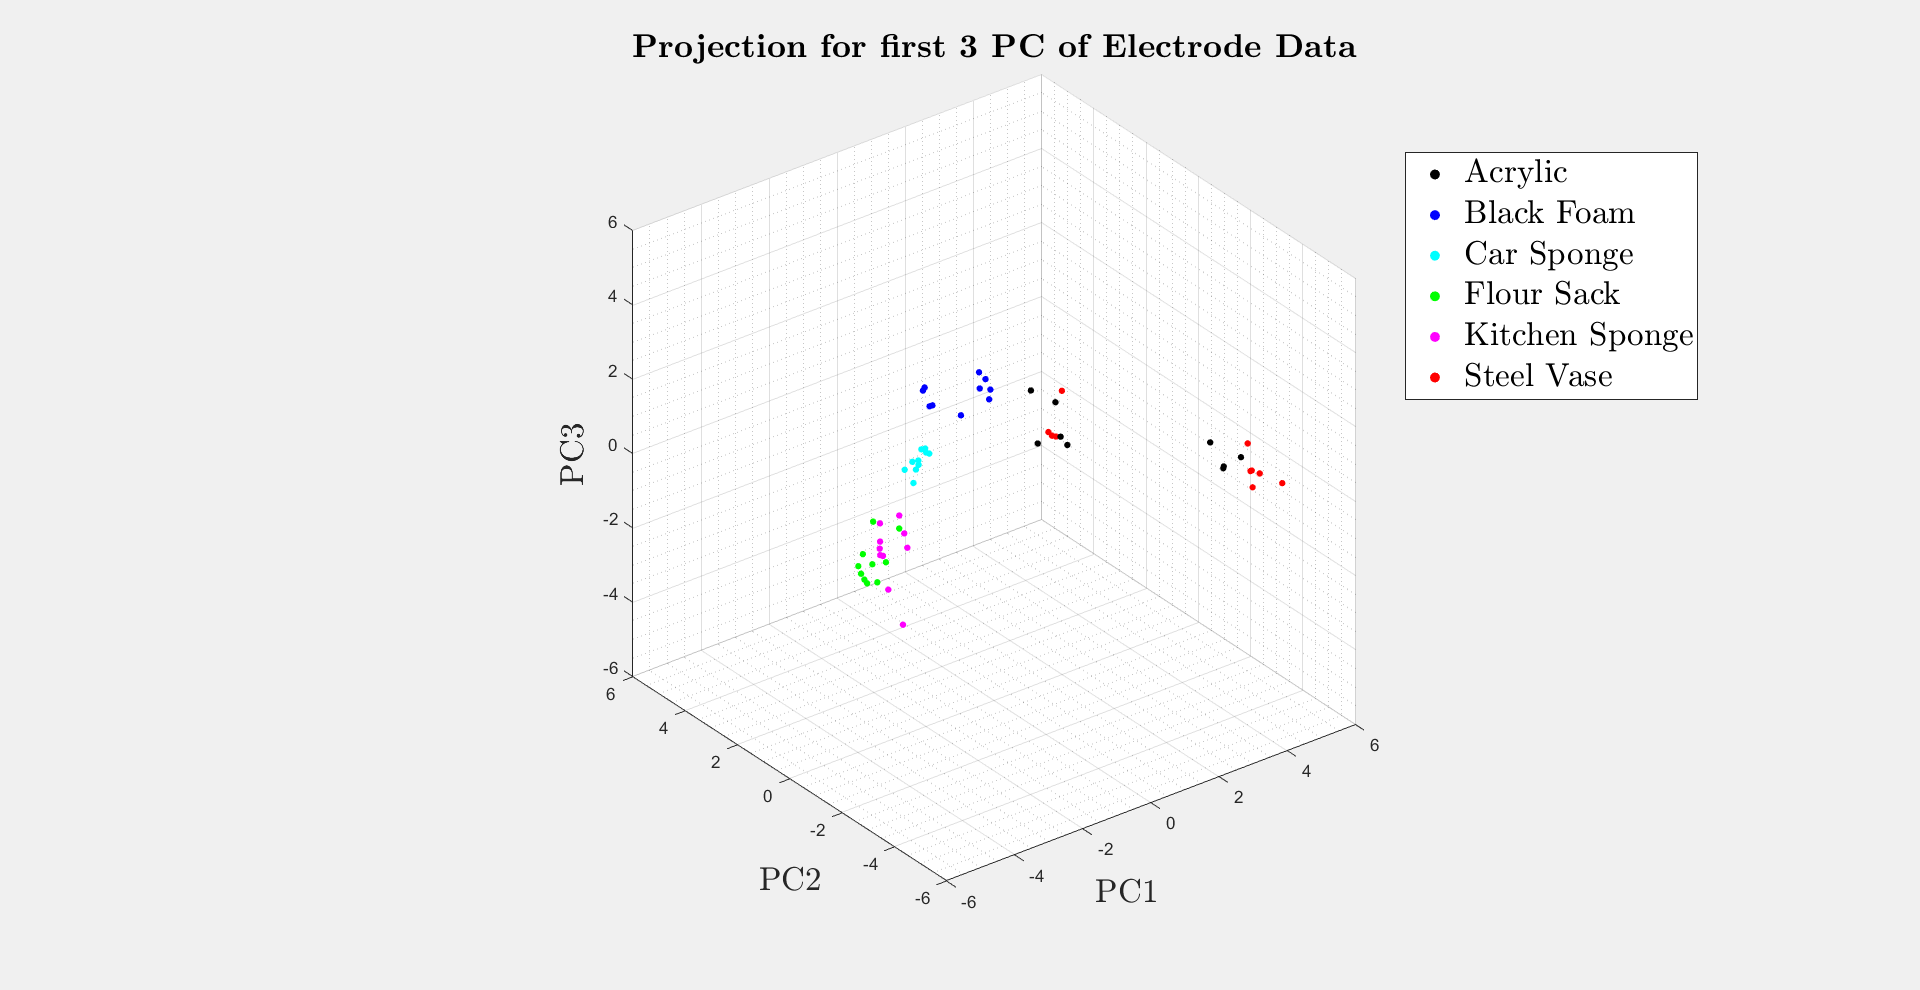

% Visualise data with first 3 PC
PC3_Ecoeff = Ecoeff(:,3); % Get THIRD column as PC3
PC2_Ecoeff = Ecoeff(:,2); % Get SECOND column as PC2
PC1_Ecoeff = Ecoeff(:,1); % Get FIRST column as PC1
EPC1 = E*PC1_Ecoeff;     % Project data onto PC1 as 1D
EPC2 = E*PC2_Ecoeff;     % Project data onto PC2 as 1D
EPC3 = E*PC3_Ecoeff;     % Project data onto PC3 as 1D

J = [EPC1 EPC2 EPC3]; % Combine projected data onto PC vectors into one data matrix
J_coeff = [PC1_Ecoeff PC2_Ecoeff PC3_Ecoeff]; % Combine PC vectors into one data matrix

electrodes_data = [labels' J];

% Plot the 3D projected Data onto top 3 variance PC
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')

scatter3(J((1:10),1),J((1:10),2),J((1:10),3),15, colourNames{1},'filled')
hold on;
for i = 1:5
    scatter3(J(((i*10)+1:(i+1)*10),1),J(((i*10)+1:(i+1)*10),2),J(((i*10)+1:(i+1)*10),3),15,colourNames{i+1},'filled')
end
grid on
grid minor
xlabel('PC1','Interpreter', 'Latex', 'Fontsize', 20)
ylabel('PC2','Interpreter', 'Latex', 'Fontsize', 20)
zlabel('PC3','Interpreter', 'Latex', 'Fontsize', 20)
legend('Acrylic','Black Foam', 'Car Sponge', 'Flour Sack', 'Kitchen Sponge', 'Steel Vase','Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
axis([-6 6 -6 6 -6 6])
axis square
title('\textbf{Projection for first 3 PC of Electrode Data}','Interpreter', 'Latex', 'Fontsize', 20)

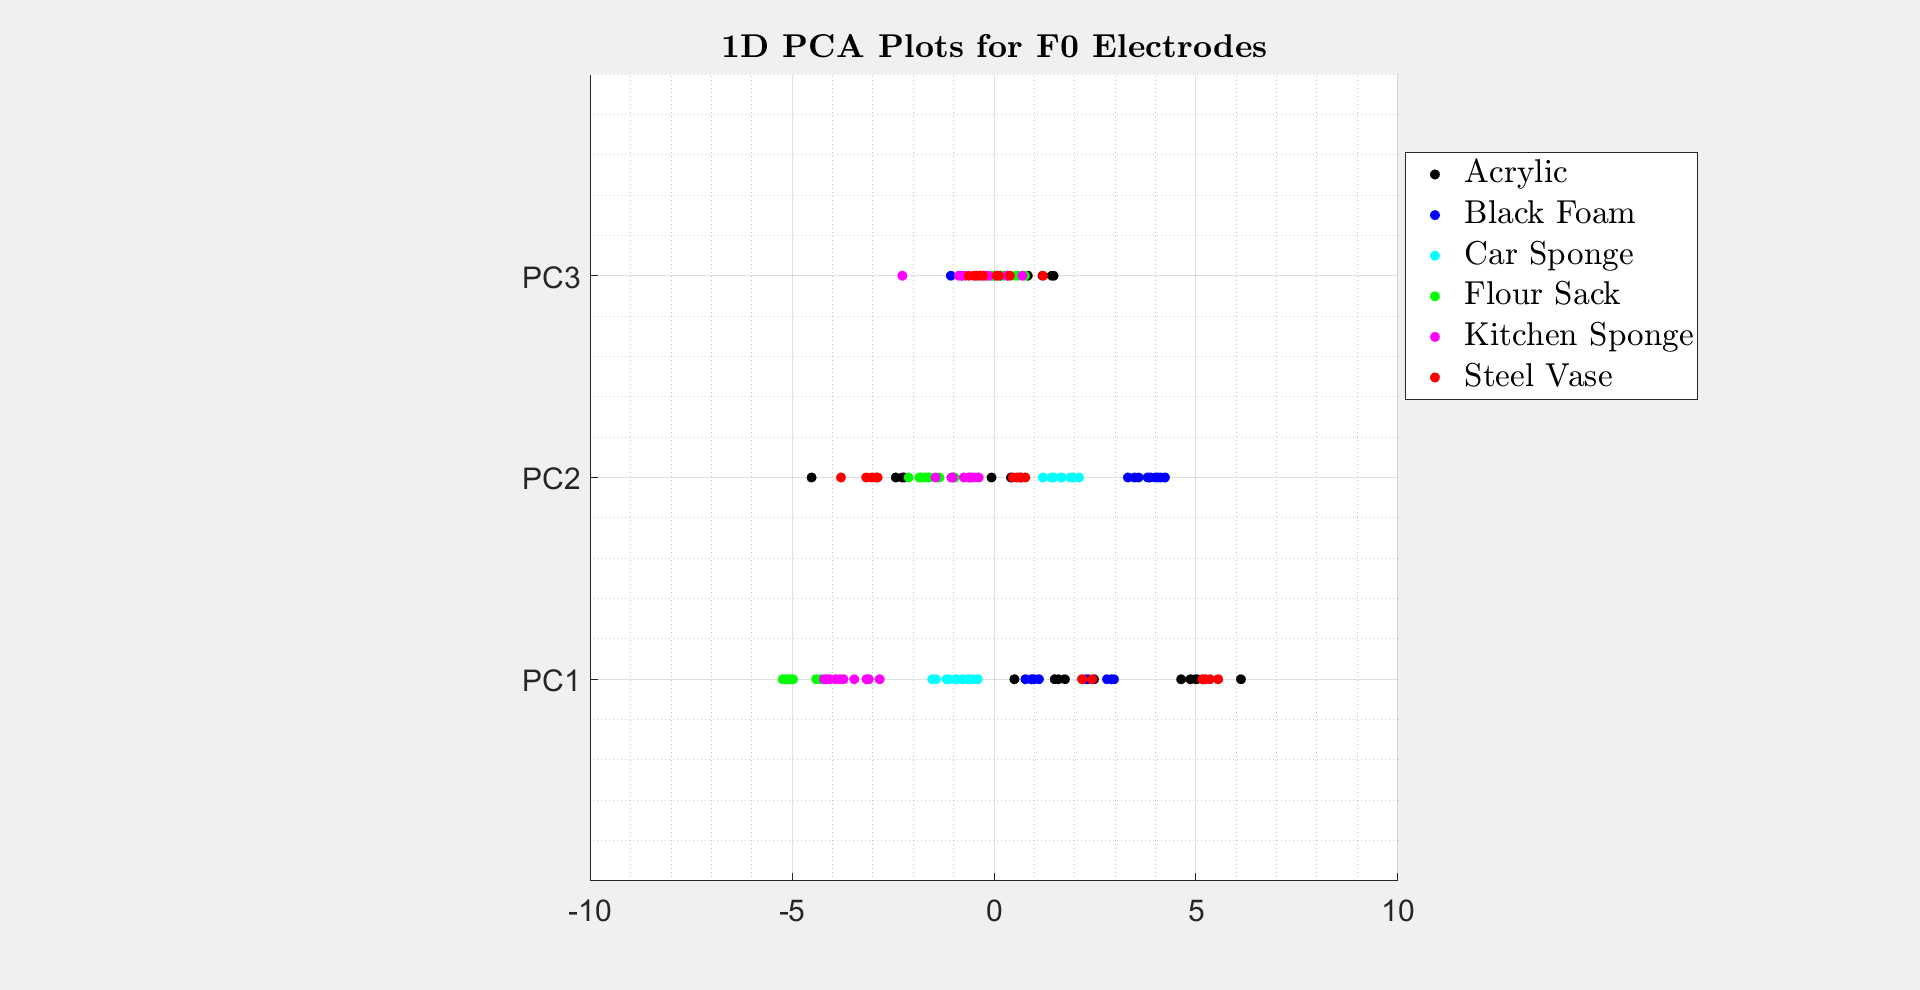

% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');

% Create projected matrix onto the Principle Components 1D
figure('Position', get(0, 'Screensize')) 
set(gcf, 'Visible','on')
hAxes = axes('NextPlot','add','DataAspectRatio',[1 1 1],'YLim',[0 20],'Color','white');

plotHandles = zeros(6,10);

hold on
    for i = 1:6
        plotHandles(i,:) = scatter(hAxes, EPC1(((i-1)*10)+1:i*10),5,colourNames{i}, 'filled');
        scatter(hAxes, EPC2(((i-1)*10)+1:i*10),10,colourNames{i}, 'filled');  %# Plot data set 2 (show at y = 2)
        scatter(hAxes, EPC3(((i-1)*10)+1:i*10),15,colourNames{i}, 'filled');  %# Plot data set 3 (show at y = 3) 
    end
hold off

legend(plotHandles(:,1), legNames,'Interpreter', 'Latex', 'Fontsize', 20, 'Location', 'best')
grid on
grid minor
xlim([-10 10])
yticks([5, 10, 15]) % Show only ticks for the 3 PC
yticklabels({'PC1', 'PC2', 'PC3'}) % Replace tick values with PC names
a = get(gca,'YTickLabel');
set(gca,'YTickLabel',a, 'fontsize',18)
title('\textbf{1D PCA Plots for F0 Electrodes}', 'Interpreter', 'Latex', 'Fontsize', 20)

% saveas(gca, fullfile('figures', 'pr_b_4'), 'epsc2');